# get a glance of the data

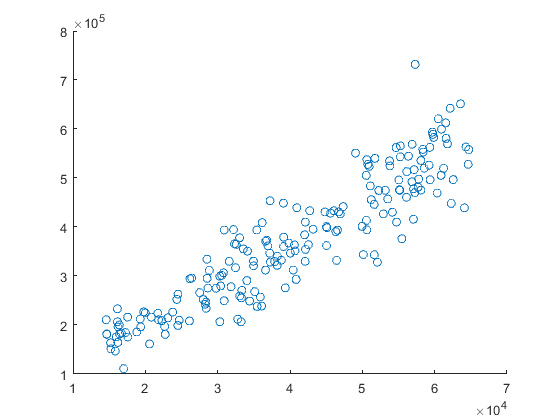


scatter(exp1.x,exp1.y)
hold on

## fit a line

[model,gof,output]=fit(exp1.x,exp1.y,"poly1")

model =      Linear model Poly1:
     model(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =       8.242  (7.728, 8.755)
       p2 =   3.686e+04  (1.477e+04, 5.894e+04)

gof = 包含以下字段的 struct :
           sse: 5.1667e+11
       rsquare: 0.8420
           dfe: 188
    adjrsquare: 0.8411
          rmse: 5.2424e+04


output = 包含以下字段的 struct :
        numobs: 190
      numparam: 2
     residuals: [190×1 double]
      Jacobian: [190×2 double]
      exitflag: 1
     algorithm: 'QR factorization and solve'
    iterations: 1


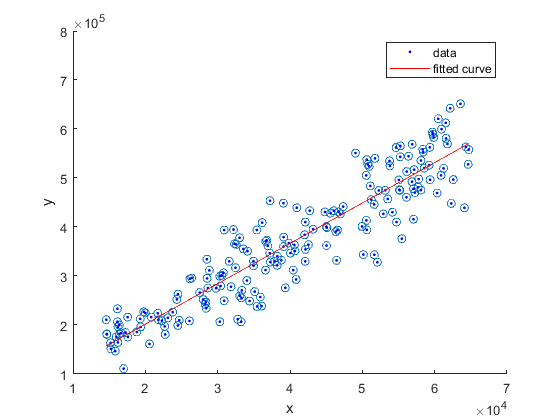

plot(model,exp1.x,exp1.y)

## let's look at the result

hold off

% this shows the goodness of the fit
gof

gof = 包含以下字段的 struct :
           sse: 5.1667e+11
       rsquare: 0.8420
           dfe: 188
    adjrsquare: 0.8411
          rmse: 5.2424e+04


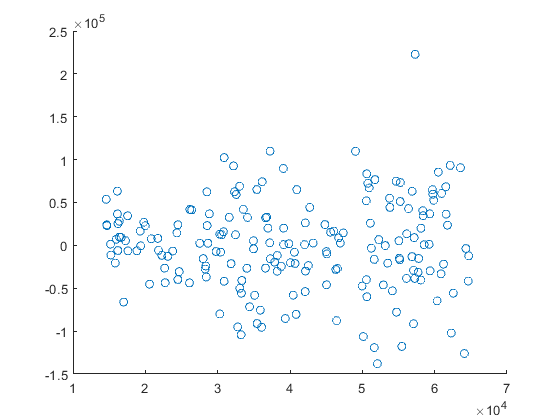

% let's plot the residuals
scatter(exp1.x,output.residuals)

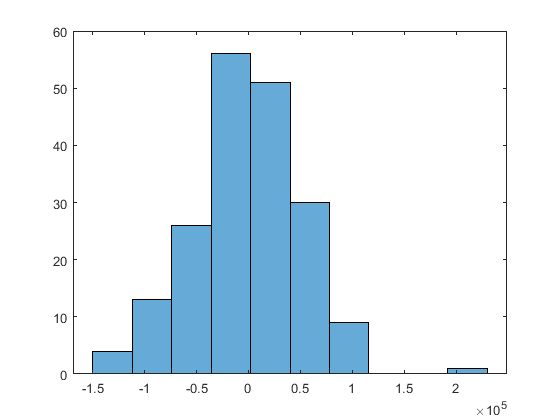

histogram(output.residuals,10)

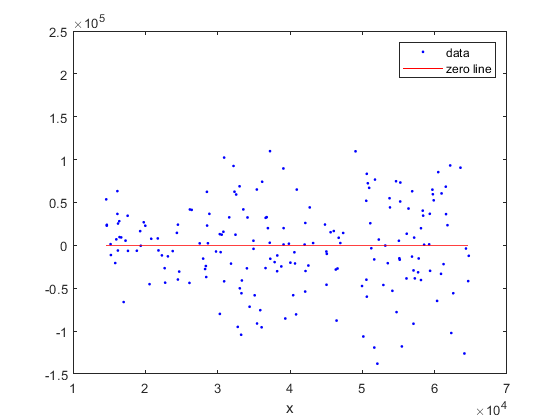

% this residual plot is better looking
plot(model,exp1.x,exp1.y,"residuals")

model

model =      Linear model Poly1:
     model(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =       8.242  (7.728, 8.755)
       p2 =   3.686e+04  (1.477e+04, 5.894e+04)

gof

gof = 包含以下字段的 struct :
           sse: 5.1667e+11
       rsquare: 0.8420
           dfe: 188
    adjrsquare: 0.8411
          rmse: 5.2424e+04


ans = 	1.0e+05 *

    5.6074
    4.5521
    4.5669
    1.8188
    3.0907
    5.1934
    5.3540
    5.2876
    1.7228
    1.7912
